syms ei ec ecp il ilp c l r2 r3 s

ilp=(1/l)*(ei-ec-r2*il)

$$ilp = -\frac{\mathrm{ec}-\text{ei}+\mathrm{il}\,r_{2}}{l}$$

ecp=(1/c)*((ei-ec)/r3+il-1/8*ec.^3)

$$ecp = -\frac{\frac{\mathrm{ec}-\text{ei}}{r_{3}}-\mathrm{il}+\frac{{\mathrm{ec}}^{3}}{8}}{c}$$

xe=[il,ec];
% salida %%%
y=il

$$y = \mathrm{il}$$

%%%%%%%%%%%%
ts=2;
zeta=1;
A=jacobian([ilp,ecp],xe)

$$A = \left(\begin{array}{cc} -\frac{r_{2}}{l} & -\frac{1}{l}\\ \frac{1}{c} & -\frac{\frac{3\,{\mathrm{ec}}^{2}}{8}+\frac{1}{r_{3}}}{c} \end{array}\right)$$

B=jacobian([ilp,ecp],ei)

$$B = \left(\begin{array}{c} \frac{1}{l}\\ \frac{1}{c\,r_{3}} \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

D=jacobian(y,ei)

$$D = 0$$


F_transSimb=C*(inv(s*eye(2)-A))*B+D

$$F\_transSimb = \begin{array}{l} \frac{3\,r_{3}\,{\mathrm{ec}}^{2}+8\,c\,r_{3}\,s+8}{\sigma_{1}}-\frac{8}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=8\,r_{2}+8\,r_{3}+8\,l\,s+3\,{\mathrm{ec}}^{2}\,r_{2}\,r_{3}+8\,c\,r_{2}\,r_{3}\,s+8\,c\,l\,r_{3}\,s^{2}+3\,{\mathrm{ec}}^{2}\,l\,r_{3}\,s \end{array}$$


c=1/2

c = 0.5000

l=2

l = 2

r2=2

r2 = 2

r3=1

r3 = 1

e0=5

e0 = 5

ec=3.9148

ec = 3.9148

ei=8.9148

ei = 8.9148


%%%%%%%%%%%%%%%%%%%%%%
A=double(eval(A))

A =    -1.0000   -0.5000
    2.0000  -13.4942


B=double(eval(B))

B =     0.5000
    2.0000


C=double(eval(C))

C =      1     0


D=double(eval(D))

D = 0

[num,den]=ss2tf(A,B,C,D)

num =          0    0.5000    5.7471


den =     1.0000   14.4942   14.4942


ft=tf(num,den)

ft =
 
      0.5 s + 5.747
  ---------------------
  s^2 + 14.49 s + 14.49
 
Continuous-time transfer function.



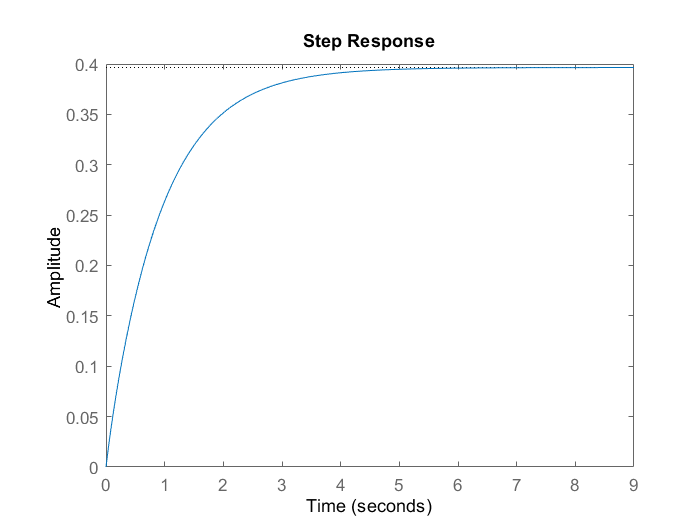

step(ft)

%%%%%%%%%%%%%%%%%%%%%
wn=4/(ts*zeta)

wn = 2

polos=roots([1 2*zeta*wn wn^2])

polos =     -2
    -2


K=acker(A,B,polos)

K =     1.0500   -5.5096


%%%%%%%%%%%%%%%%%%%%%%Ess=0 Escalon
polosEss=conv(polos,[1 10*wn*zeta])

polosEss =     -2   -42   -40


Aempaq=[A(1,1),A(1,2),0;A(2,1),A(2,2),0;-C(1,1),-C(1,2),0]

Aempaq =    -1.0000   -0.5000         0
    2.0000  -13.4942         0
   -1.0000         0         0


Bempaq=[B(1,1);B(2,1);0]

Bempaq =     0.5000
    2.0000
         0


K1=acker(Aempaq,Bempaq,polosEss)

K1 =   286.7504  -36.9347 -584.6404


%%%%%%Observador
tsa=ts/10;
wna=4/(tsa*zeta)

wna = 20

obs=[C;C*A]

obs =     1.0000         0
   -1.0000   -0.5000


det(obs)

ans = -0.5000

pdo=conv([1 2*tsa*zeta wna^2],[1 10*wna*zeta])

pdo = 	1.0e+04 *

    0.0001    0.0200    0.0480    8.0000


phia= A^3+pdo(2)*A^2+pdo(3)*A+pdo(4)*eye(2)

phia = 	1.0e+05 *

    0.7953    0.0111
   -0.0446    1.0738


L=phia*(inv(obs))*[1;0]

L = 	1.0e+05 *

    0.7731
   -2.1923


%%%%%%%%% tm=0.7s
tm=0.7

tm = 0.7000

polosEssT=conv(polosEss,[1 10*wn*zeta])

polosEssT =     -2   -82  -880  -800


polosEssT=conv(polosEssT,[1 10*wn*zeta])

polosEssT =           -2        -122       -2520      -18400      -16000


ftdelay=tf([1],[(tm^2)/2 tm 1])

ftdelay =
 
            1
  ---------------------
  0.245 s^2 + 0.7 s + 1
 
Continuous-time transfer function.



ft2=ft*ftdelay

ft2 =
 
                    0.5 s + 5.747
  --------------------------------------------------
  0.245 s^4 + 4.251 s^3 + 14.7 s^2 + 24.64 s + 14.49
 
Continuous-time transfer function.



[A1,B1,C1,D1]=tf2ss([0.5,5.747],[0.245,4.251,14.7,24.64,14.49])

A1 =   -17.3510  -60.0000 -100.5714  -59.1429
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B1 =      1
     0
     0
     0


C1 =          0         0    2.0408   23.4571


D1 = 0

Aempaq1=[A1(1,1),A1(1,2),A1(1,3),A1(1,4),0;A1(2,1),A1(2,2),A1(2,3),A1(2,4),0;A1(3,1),A1(3,2),A1(3,3),A1(3,4),0;A1(4,1),A1(4,2),A1(4,3),A1(4,4),0;-C1(1,1),-C1(1,2),-C1(1,3),-C1(1,4),0]

Aempaq1 =   -17.3510  -60.0000 -100.5714  -59.1429         0
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0   -2.0408  -23.4571         0


Bempaq1=[B1(1,1);B1(2,1);B1(3,1);B1(4,1);0]

Bempaq1 =      1
     0
     0
     0
     0


KDelay=acker(Aempaq1,Bempaq1,polosEssT)

KDelay = 	1.0e+13 *

    0.0000    0.0000    0.0789    7.6338   -0.7717
